addpath(genpath('helpers'));
addpath(genpath('libraries/buzcode/'));


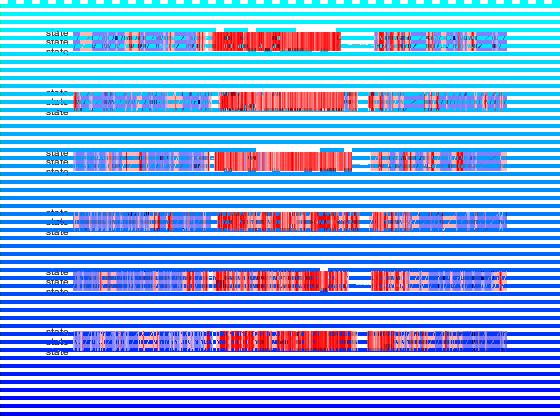

ax =   Axes with properties:

             XLim: [0 35351]
             YLim: [0.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.8224 0.7750 0.1026]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 33810]
             YLim: [0.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.6799 0.7750 0.1026]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 34341]
             YLim: [0.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5374 0.7750 0.1026]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 33977]
             YLim: [0.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.3950 0.7750 0.1026]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 34575]
             YLim: [0.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.2525 0.7750 0.1026]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 33556]
             YLim: [0.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.1026]
            Units: 'normalized'

  Show all properties


active_num_experiments = length(active_experiment_names);

plottingOptions.vertical_state_mode = 'combined';
% plottingOptions.plot_variable = 'behavioral_epoch';
plottingOptions.plot_variable = 'behavioral_state';
    
fig = figure();

% Loop through each experiment:
for expt_index = 1:active_num_experiments
    expt_info.index = expt_index;
    expt_info.name = active_experiment_names{expt_index};
    
    across_experiment_results{expt_index}.active_processing.definitions.behavioral_epoch.classColors = [0.0, 0.5, 0.0
               0.2, 1.0, 0.2
               0.0, 0.2, 0.0];
    
    across_experiment_results{expt_index}.active_processing.definitions.behavioral_state.classColors = [0.5, 0.5, 1.0
               0.7, 0.7, 1.0
               1.0, 0.7, 0.7
               1.0, 0.0, 0.0];

    subplot(active_num_experiments, 1, expt_index);
    [ax] = fnPlotStateDiagram(across_experiment_results{expt_index}.active_processing, plottingOptions);
    title(expt_info.name)
end